% Learn Adapt
% Trying to figure out if my reflected decoder is real

binnedIsoHC = convert2BDF2Binned; % normed
binnedReflectedBC = convert2BDF2Binned; % Normed


% Only use the 4 wrist muslces
binnedIsoHC = ReduceBinnedToFourWristMuscles(binnedIsoHC);
binnedReflectedBC = ReduceBinnedToFourWristMuscles(binnedReflectedBC);

% Now build the reflected decoder, and test it on the reflected brain data.
% Compare to the actual cursor position (predictions)
opts = BuildModelGUI;
N2E_IsoHC  = BuildModel(binnedIsoHC,opts);
% Build EMG to Force model
opts = BuildModelGUI; %(in=EMG, out=cursor position, ***PAY ATTENTION length = 250ms****, polyn order=0 )
E2F_IsoHC  = BuildModel(binnedIsoHC,opts);


% Make reflected EMG to Force decoder--------------------------------------
 FCRweightsInd = strmatch('FCR',N2E_IsoHC.outnames(1,:));
 ECRweightsInd = strmatch('ECR',N2E_IsoHC.outnames(1,:));
 noOfWeights = opts.fillen/.05;
 FCRindices = fliplr((noOfWeights*FCRweightsInd:-1:noOfWeights*FCRweightsInd-noOfWeights+1));
 FCR2Fweights = E2F_IsoHC.H(FCRindices,:);
 ECRindices = fliplr((noOfWeights*ECRweightsInd:-1:noOfWeights*ECRweightsInd-noOfWeights+1));
 ECR2Fweights = E2F_IsoHC.H(ECRindices,:);
 E2F_IsoHCreflected = E2F_IsoHC;
 E2F_IsoHCreflected.H(ECRindices,:) = FCR2Fweights;
 E2F_IsoHCreflected.H(FCRindices,:) = ECR2Fweights;

  [PredDataFromIsoHC_EMGs] = predictSignals(N2E_IsoHC, binnedReflectedBC);
  PredDataFromIsoHC_EMGs.emgdatabin=PredDataFromIsoHC_EMGs.preddatabin;
  [PredDataFromIsoHC_CPosNormal] = predictSignals_predMIMO3(E2F_IsoHC, PredDataFromIsoHC_EMGs);
  [PredDataFromIsoHC_CPosReflect] = predictSignals_predMIMO3(E2F_IsoHCreflected, PredDataFromIsoHC_EMGs);
  
  

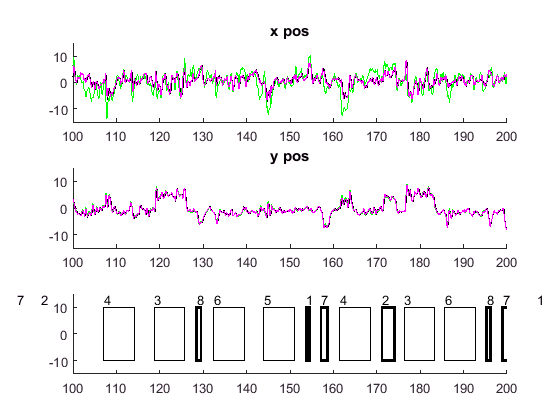

 % figure; MillerFigure; hold on
  subplot(3,1,1); hold on
  title('x pos')
  plot(binnedReflectedBC.timeframe(14:end),binnedReflectedBC.cursorposbin(14:end,1),'k');
  plot(binnedReflectedBC.timeframe(14:end),PredDataFromIsoHC_CPosNormal.preddatabin(:,1),'g');
  plot(binnedReflectedBC.timeframe(14:end),PredDataFromIsoHC_CPosReflect.preddatabin(:,1),'m');
  tt = binnedReflectedBC.trialtable;
  xlim([100 200]); ylim([-15 15])
   subplot(3,1,3); hold on
  for ind=1:length(binnedReflectedBC.trialtable)
      text(tt(ind,6),13,num2str(tt(ind,10)))
      rectangle('Position',[tt(ind,6), -10, (tt(ind,8)-tt(ind,6)), 20])
      if tt(ind,9)==82
           rectangle('Position',[tt(ind,6), -10, (tt(ind,8)-tt(ind,6)), 20],'LineWidth',2)
      end
  end
  xlim([100 200]); ylim([-15 15])
  %figure; MillerFigure; hold on
  subplot(3,1,2); hold on
  title('y pos')
  plot(binnedReflectedBC.timeframe(14:end),binnedReflectedBC.cursorposbin(14:end,2),'k');
  plot(binnedReflectedBC.timeframe(14:end),PredDataFromIsoHC_CPosNormal.preddatabin(:,2),'g');
  plot(binnedReflectedBC.timeframe(14:end),PredDataFromIsoHC_CPosReflect.preddatabin(:,2),'m');
  xlim([100 200]); ylim([-15 15])

% Plot predicted versus actual